% -------------------------------------------------------------------------
% Ducted propeller design example.
% -------------------------------------------------------------------------

% -------------------------------------------------------------------------
addpath ./SourceCode ../SourceCode ../../SourceCode

clr,

% Load inputs by running the Example_input script:
Example_input

ans = struct with fields:
              part1: '------ Performance inputs ------'
                  Z: 3
                  N: 4800
                  D: 0.0660
                 Vs: 1.5000
                 Js: 0.2841
                  L: 11.0584
              CTDES: 12.9909
              part2: '------ Geometry inputs ------'
                 Mp: 20
                 Np: 20
                  R: 0.0330
               Rhub: 0.0150
                 XR: [0 0.1111 0.2222 0.3333 0.4444 0.5556 0.6667 0.7778 0.8889 1]
                XVA: [1 1 1 1 1 1 1 1 1 1]
                XVT: [0 0 0 0 0 0 0 0 0 0]
                XCD: [0.0080 0.0080 0.0080 0.0080 0.0080 0.0080 0.0080 0.0080 0.0080 0.0080]
               XCoD: [Inf 0.6194 0.4808 0.3997 0.3422 0.2976 0.2611 0.2303 0.2036 0.1800]
              t0oc0: [0 0.0167 0.0333 0.0500 0.0667 0.0833 0.1000 0.1167 0.1333 0.1500]
              skew0: [0 -1.1111 -2.2222 -3.3333 -4.4444 -5.5556 -6.6667 -7.7778 -8.8889 -10]
              rake0: [0 -0.0089 -0.01

 
Computing rotor-duct interaction...be patient...
 


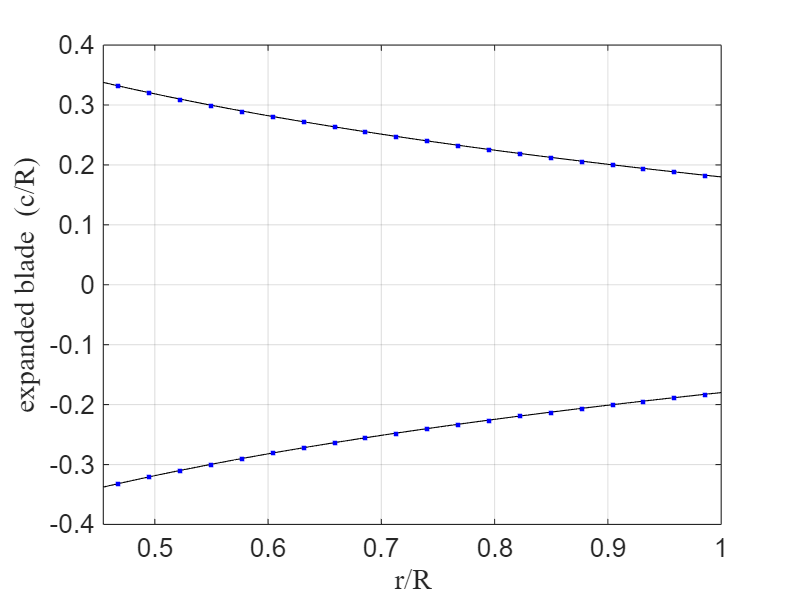

--------- Begin circulation optimization
 
The max  G_res for iteration  1 is: 1
The max  G_res for iteration  2 is: 0.15783
The max  G_res for iteration  3 is: 0.052992
The max  G_res for iteration  4 is: 0.013237
The max  G_res for iteration  5 is: 0.0037445
The max  G_res for iteration  6 is: 0.00082013
The max  G_res for iteration  7 is: 0.00014548
The max  G_res for iteration  8 is: 2.5777e-05
 
Design optimization complete
 
Forces after circulation optimization:
    Js = 0.28409
    KT = 0.41173
    KQ = 0.052377
    CT = 12.9909
  EFFY = 0.35543
ADEFFY = 0.45711
    QF = 0.77755
 
 


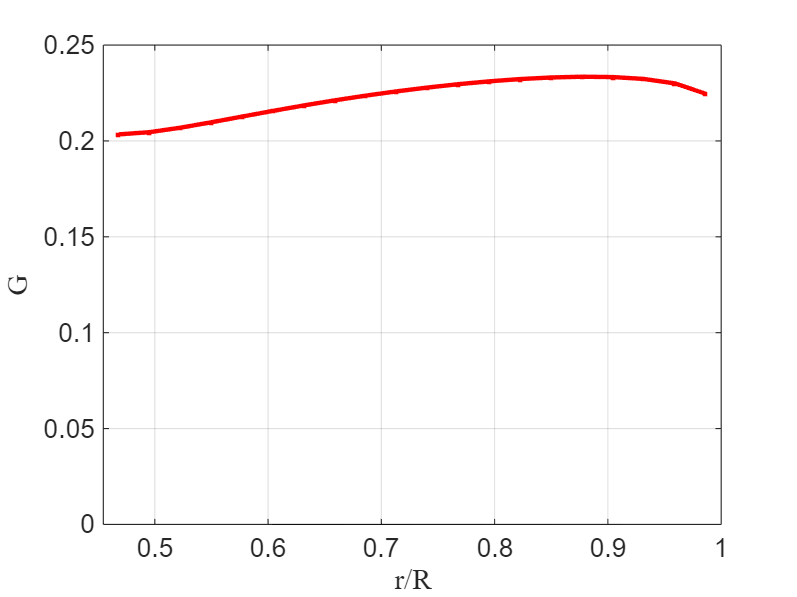

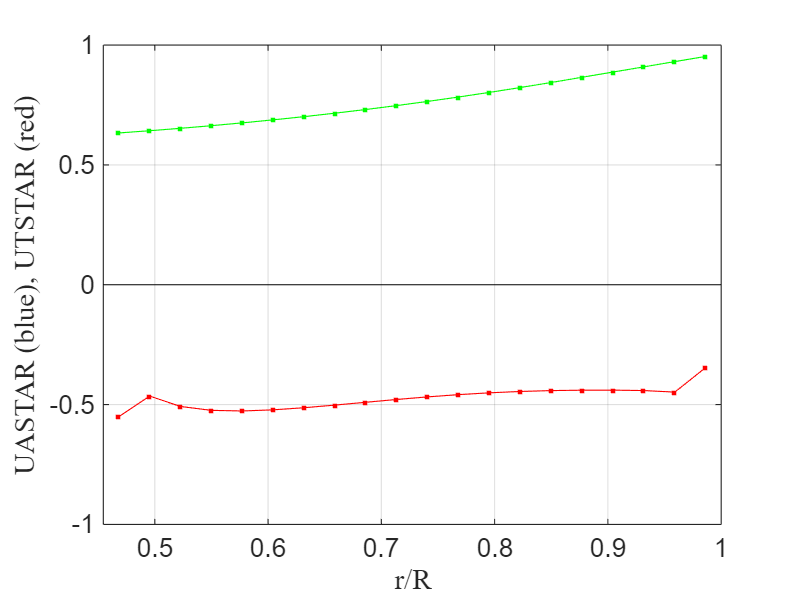

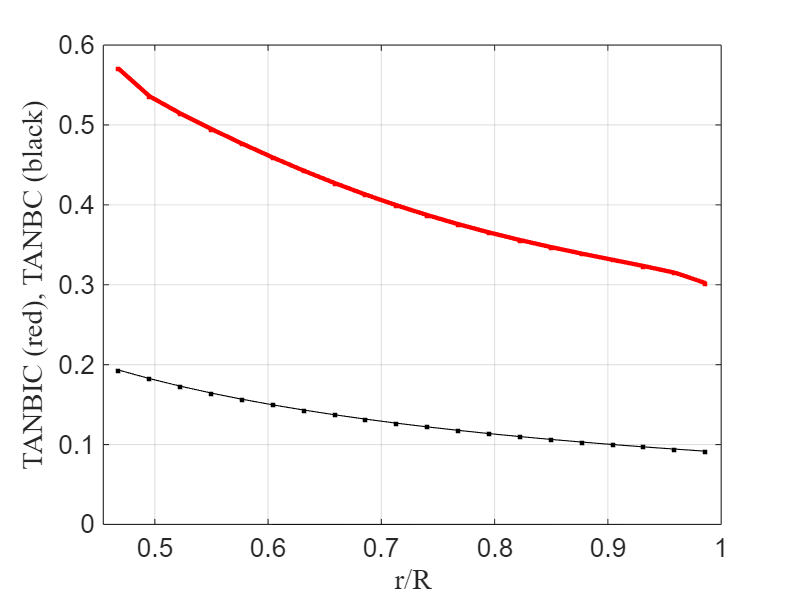

pt = struct with fields:
    filename: 'OpenProp'
        date: '26-Nov-2025'
       notes: 'Ducted propeller from Sutbblefield (2008) M.S. thesis'
       input: [1×1 struct]
      design: [1×1 struct]
    geometry: []
      states: []




% Perform design optimization
pt.design = EppsOptimizer(pt.input)

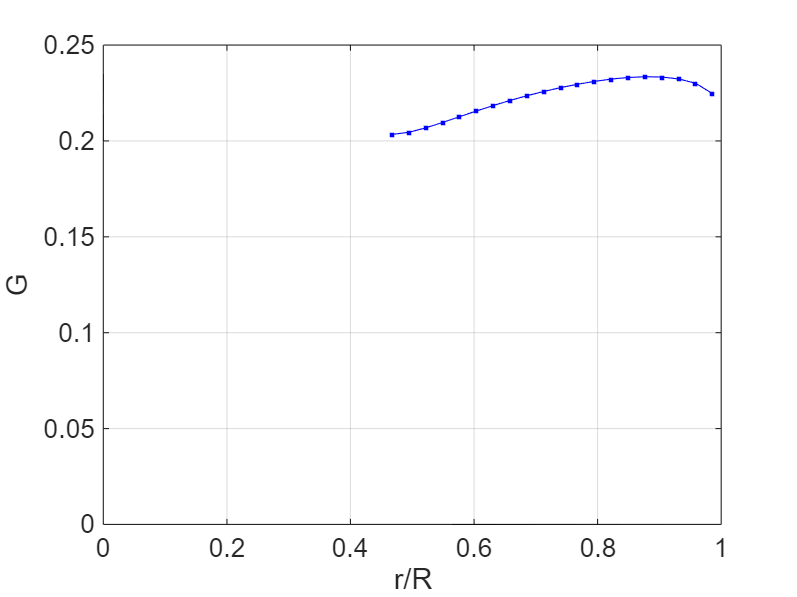


fig;
plot(pt.design.RC,pt.design.G,'.-b')
xlabel('r/R'), ylabel('G')
plotaxes,

Create graphical and text reports

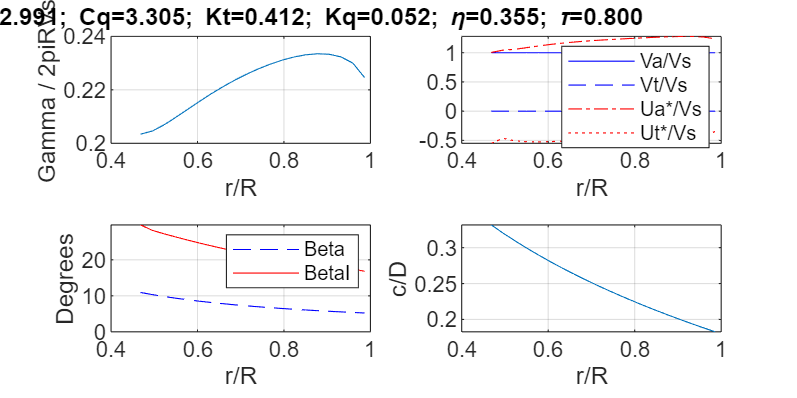

Make_Reports(pt)

Determine propeller geometry

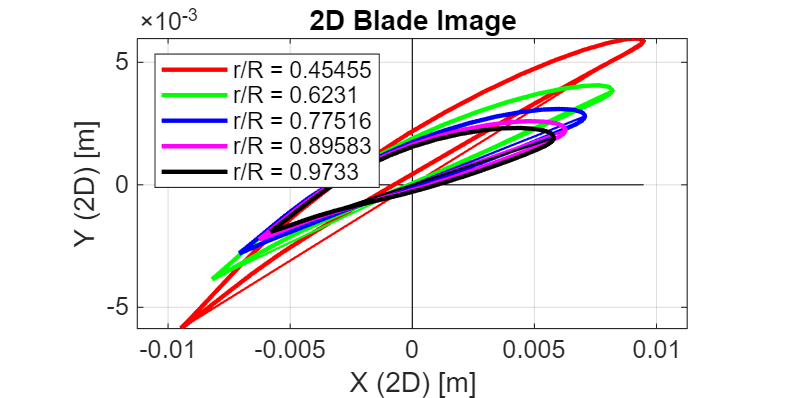

 
Computing rotor-duct interaction...be patient...
 


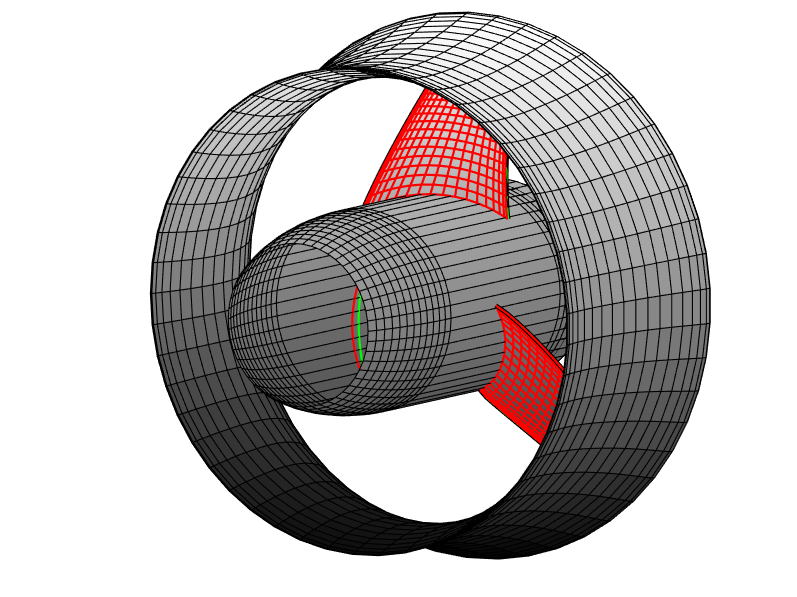

pt = struct with fields:
    filename: 'OpenProp'
        date: '26-Nov-2025'
       notes: 'Ducted propeller from Sutbblefield (2008) M.S. thesis'
       input: [1×1 struct]
      design: [1×1 struct]
    geometry: [1×1 struct]
      states: []


pt.geometry = Geometry(pt)

close all,
pt.input.Plot_flag = 0;

% Analyze off-design states
Js_all    = [0.4:0.05:1];     % advance coefficient
LAMBDAall = pi./Js_all;           % tip-speed ratio
pt.states = Analyze(pt,LAMBDAall)

 
Computing rotor-duct interaction...be patient...
 
 
Forces for state:  L = 7.854 , Js = 0.4
 
    Js = 0.4
    KT = 0.34032
    KQ = 0.045319
    CT = 5.4164
  EFFY = 0.47808
 
The max error for iteration 10 is: 0.0034997
 
------------------------------------------------
 
 
 
 
Forces for state:  L = 6.9813 , Js = 0.45
 
    Js = 0.45
    KT = 0.3032
    KQ = 0.041419
    CT = 3.8128
  EFFY = 0.52427
 
The max error for iteration  7 is: 0.0026218
 
------------------------------------------------
 
 
 
 
Forces for state:  L = 6.2832 , Js = 0.5
 
    Js = 0.5
    KT = 0.26202
    KQ = 0.036881
    CT = 2.6689
  EFFY = 0.56536
 
The max error for iteration  6 is: 0.0011868
 
------------------------------------------------
 
 
 
 
Forces for state:  L = 5.712 , Js = 0.55
 
    Js = 0.55
    KT = 0.21712
    KQ = 0.031743
    CT = 1.8278
  EFFY = 0.59873
 
The max error for iteration  4 is: 0.0028424
 
------------------------------------------------
 
 
 
 
Forces for state:  L = 5

pt = struct with fields:
    filename: 'OpenProp'
        date: '26-Nov-2025'
       notes: 'Ducted propeller from Sutbblefield (2008) M.S. thesis'
       input: [1×1 struct]
      design: [1×1 struct]
    geometry: [1×1 struct]
      states: [1×1 struct]


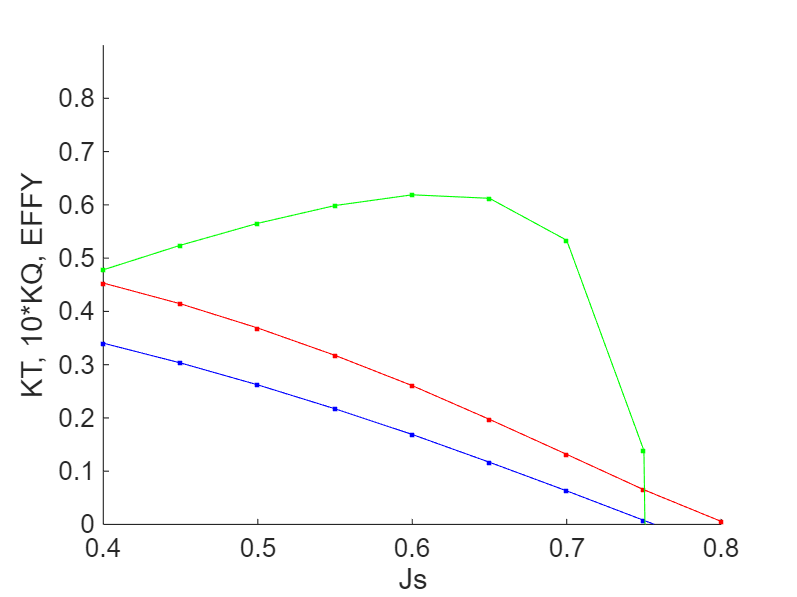



figure, hold on,
plot(pt.states.Js,   pt.states.KT  ,'.-b')
plot(pt.states.Js,10*pt.states.KQ  ,'.-r')
plot(pt.states.Js,   pt.states.EFFY,'.-g')

plot(pt.input.Js,   pt.design.KT  ,'x')
plot(pt.input.Js,10*pt.design.KQ  ,'x')
plot(pt.input.Js,   pt.design.EFFY,'x')

xlabel('Js'), ylabel('KT, 10*KQ, EFFY')
axis([0.4 0.8 0 0.9])